%Joseph Dearing
function xsamples=levyharmonic(N,L,n_events)
xsamples=zeros(n_events,N+1);
%indexing changed to align with that of Matlab
for i = 1:n_events
    x=zeros(1,N+1);
    x(1)=L*rand();
    x(N+1)=x(1)+L;
    for k = 2:N
        xbar=((N-(k-1))*x(k-1)+x(N+1))/(N-(k-1)+1);
        sigma=sqrt(1/(1+1/(N-(k-1))));
        x(k)=xbar+sigma*randn();
    end
xsamples(i,:)=x;
end
end

function xsamples=metroharmonic(pos,N,L,n_events,delta)
xsamples=zeros(n_events+1,N+1);
xsamples(1,:)=pos;
for i =1:n_events
    k=randi([1,N]);
    dx=delta*(2*rand()-1);
    kplus=mod(k,N)+1;
    kminus=mod(k-2,N)+1;
    xplus=xsamples(i,kplus);
    xminus=xsamples(i,kminus);
    if k==N
        xplus=xplus+L;
    end
    if k==1
        xminus=xminus-L;
    end
    xk=xsamples(i,k);
    xdash=xk+dx;
    U=1/2*((xplus-xk)^2+(xk-xminus)^2);
    Udash=1/2*((xplus-xdash)^2+(xdash-xminus)^2);
    upsilon=rand();
    xout=xsamples(i,:);
    if upsilon<exp(-(Udash-U))
        xout(k)=xdash;
    end
    xout(N+1)=xout(1)+L; %Enforcing periodicity
    xsamples(i+1,:)=xout;        
end
end


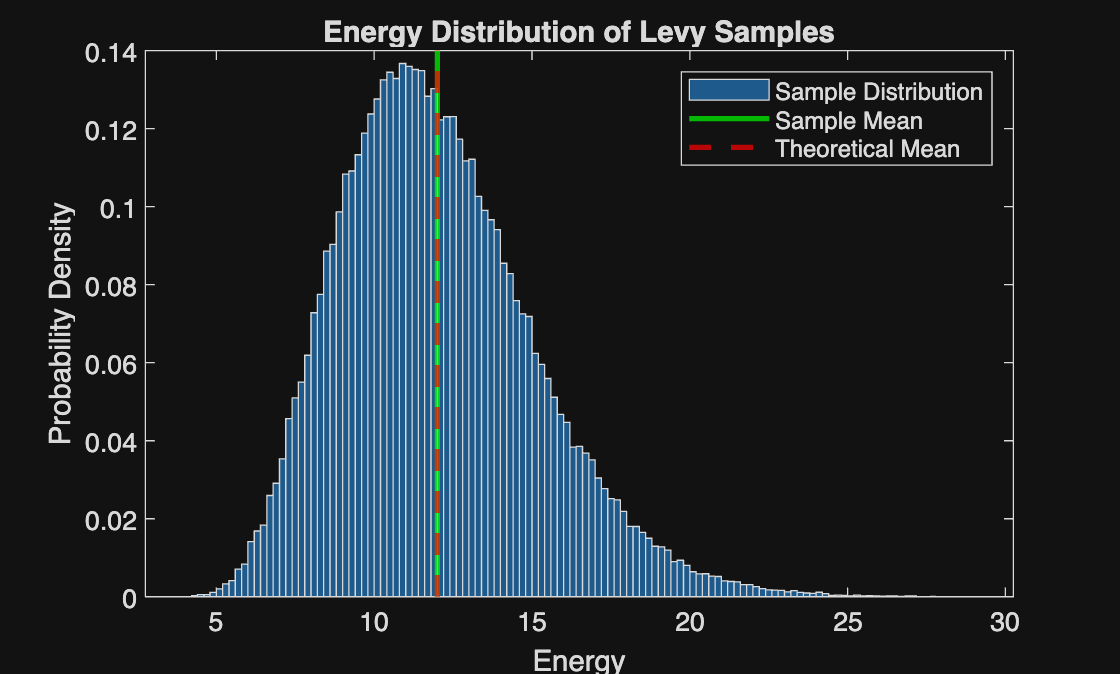

function xsamples=hmcharmonic(pos,N,L,n_events,epsilon,I)
xsamples=zeros(n_events+1,N+1);
xsamples(1,:)=pos;
for i=1:n_events
    x=xsamples(i,:);
    xtilda=x;
    p=randn(1,N);
    E=0.5*(sum(diff(x).^2))+0.5*sum(p.^2);
    grad=2*xtilda(1:N)-xtilda(2:N+1)-[xtilda(N)-L,xtilda(1:N-1)];
    p=p-0.5*epsilon*grad;
    for l =1:I
        xtilda(1:N)=xtilda(1:N)+epsilon*p;
        xtilda(N+1)=xtilda(1)+L;
        if l<I
            grad=2*xtilda(1:N)-xtilda(2:N+1)-[xtilda(N)-L,xtilda(1:N-1)];
            p=p-0.5*epsilon*grad;

        end
    end
    grad=2*xtilda(1:N)-xtilda(2:N+1)-[xtilda(N)-L,xtilda(1:N-1)];
    p=p-0.5*epsilon*grad;
    Etilda=0.5*(sum(diff(xtilda).^2))+0.5*sum(p.^2);
    upsilon=rand();
    if upsilon<exp(-(Etilda-E))
        x=xtilda;
    end
    xsamples(i+1,:)=x;
end
end

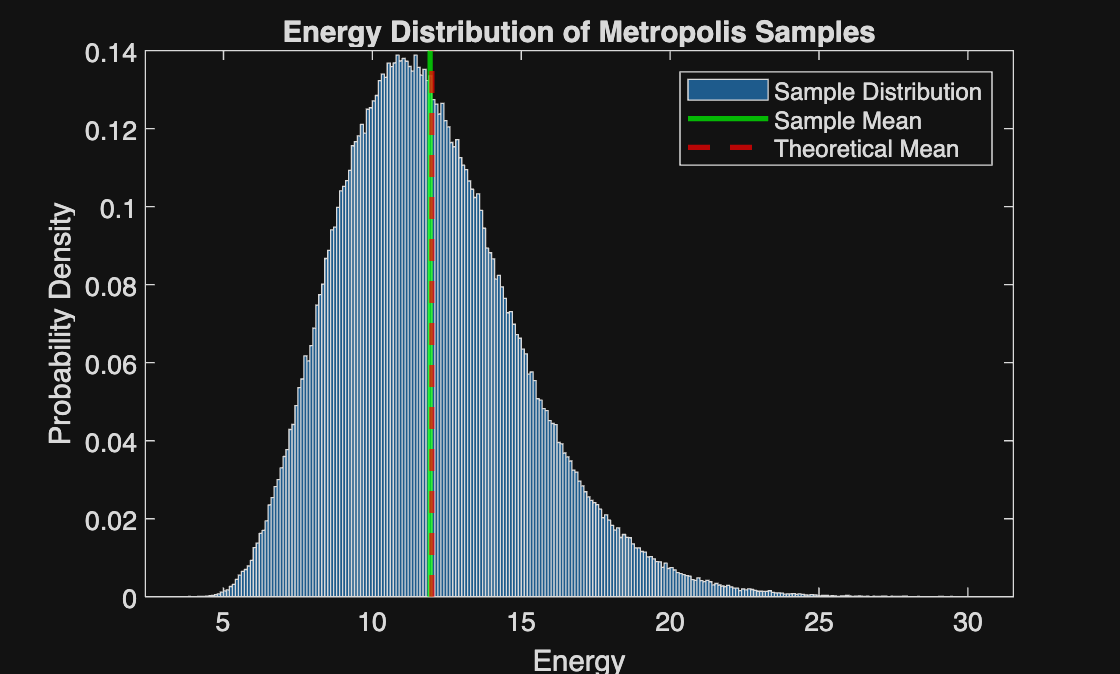

%Levy
N=20;
L=10;
n_events=100000;
xsamples=levyharmonic(N,L,n_events);
diffs=diff(xsamples,1,2);
%E=sum from k=1 to N of (x.k-x.(k-1))^2
E=0.5*sum(diffs.^2,2);
Emean_theoretical=(L^2/N+N-1)/2;

Emean_sample=mean(E);
histogram(E,"Normalization","pdf");
xline(Emean_sample,'g','LineWidth',2);
xline(Emean_theoretical,'--r','LineWidth',2);
xlabel("Energy");
ylabel("Probability Density");
title('Energy Distribution of Levy Samples');
legend('Sample Distribution','Sample Mean','Theoretical Mean');

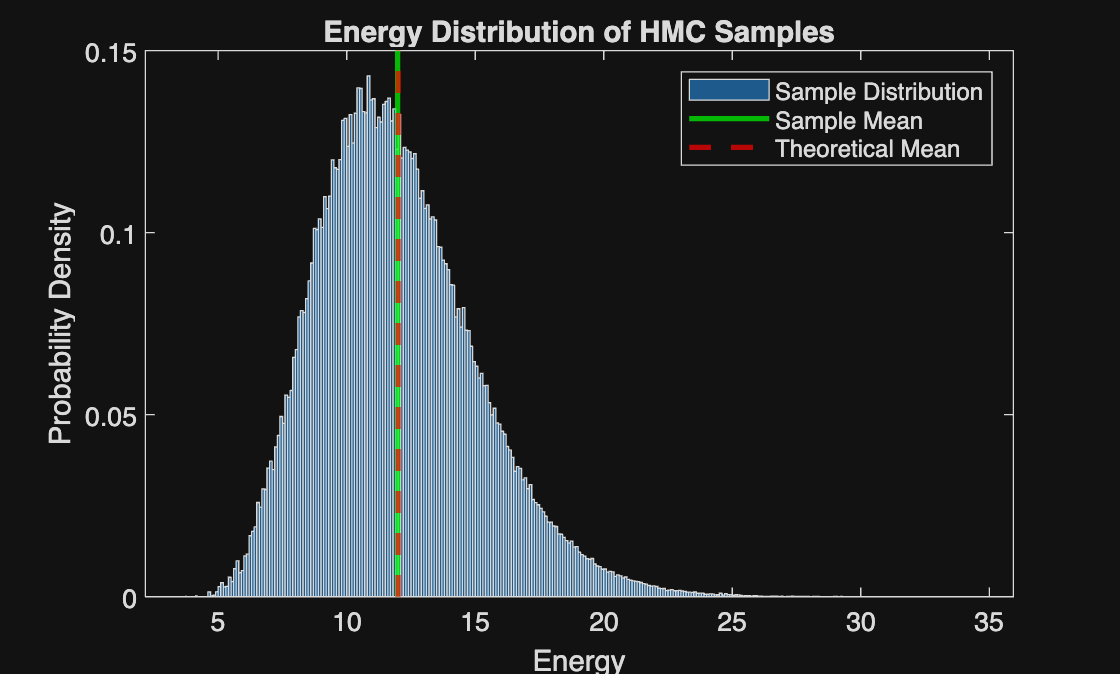

%Metro
N=20;
L=10;
n_events=1000000;
delta=1;
pos=(0:N)*L/N;
xsamples=metroharmonic(pos,N,L,n_events,delta);
diffs=diff(xsamples,1,2);
E=0.5*sum(diffs.^2,2);
burn=floor(0.1*n_events);%Getting rid of the initial 10% of data to eliminate bias towards original position input.
E = E(burn+1:end);
Emean_theoretical=(L^2/N+N-1)/2;
Emean_sample=mean(E);

histogram(E,"Normalization","pdf");
xline(Emean_sample,'g','LineWidth',2);
xline(Emean_theoretical,'--r','LineWidth',2);
xlabel("Energy");
ylabel("Probability Density");
title('Energy Distribution of Metropolis Samples');
legend('Sample Distribution','Sample Mean','Theoretical Mean');
%HMC
N=20;
L=10;
n_events=1000000;
epsilon=0.1;
I=20;
pos=(0:N)*L/N;
xsamples=hmcharmonic(pos,N,L,n_events,epsilon,I);
diffs=diff(xsamples,1,2);
E=0.5*sum(diffs.^2,2);
burn=floor(0.1*n_events);
E = E(burn+1:end);
Emean_theoretical=(L^2/N+N-1)/2;
Emean_sample=mean(E);
histogram(E,"Normalization","pdf");
xline(Emean_sample,'g','LineWidth',2);
xline(Emean_theoretical,'--r','LineWidth',2);
xlabel("Energy");
ylabel("Probability Density");
title('Energy Distribution of HMC Samples');
legend('Sample Distribution','Sample Mean','Theoretical Mean');

We can see from the plots that all three algorithms compute the correct b-independent mean energy giving sufficient sample sizes and reasonably defined parameters. Compared to the mertoplis algorithm instead of taking a random walk we asign each particle a momentum, reducing the rejection rate. Through HMC we construct a joint probability distribution that combines the potential and the knetic energy hence we must use E=U+K.